# Aggregating multiple sur files

This guide explains how to aggregate the outputs in multiple sur files

## Reading in multiple sur files

In order to read in multiple files we need the timestamps at which they were outputted. These can be retrieved easily using

t = run.outputTimestamps

t =        86400      172800      259200      345600      432000      518400      604800      691200      777600      864000      950400     1036800     1123200     1209600     1296000     1382400     1468800     1555200     1641600     1728000     1814400     1900800     1987200     2073600     2160000     2246400     2332800     2419200     2505600


These are the output times (in seconds) for which we should have sur files. There are 29 of them. We can read all of them in like this:

surs = run.sur('type', 'solids', 'g', 0, 't', t)

surs = 1×29 cell array
    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}    {1×1 Depomod.Sur.Solids}

So we have a cell array of multiple sur files.

## Calculating the mean impact

Calculating the mean (though time) impact is a useful form of analysis. In this case we will calculate the mean impact over our 29 daily seabed impacts.

To do this we will extract the cell-by-cell deposition data from each sur and average it. This requires iterating over all sur files.

First, we'll clone the first sur, and use it to hold the averaged data (once we've compiled it). This means we can handle the averaged data in all the ways we might want.

sur = surs{1}.clone;

Next, create a structure for compoling the seabed data for all surs.

surData = zeros(length(sur.Y), length(sur.X), numel(surs));

Iterate through all surs and add the seabed masses.

for i = 1:numel(surs)
    surData(:,:, i) = surs{i}.Z;
end

Calculate the cell-by-cell mean values

meanImpact = mean(surData,3);

Add the averaged data back to the cloned sur object

sur.Z = squeeze(meanImpact); 
sur.interpolate;    

We can now analyse and plot the derived sur.

sur.area(250)

ans =           19447.8631393835

Let's plot the mean sur sandwiched between the first and last surs for context

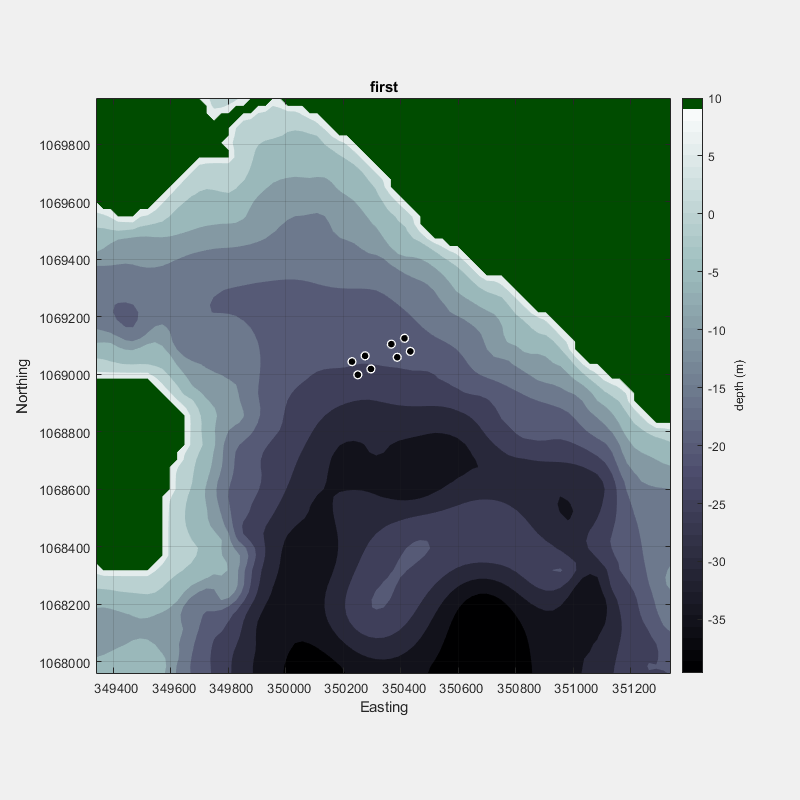

run.plot('sur', surs{1}, 'levels', [1 250 1000]);
title('first')

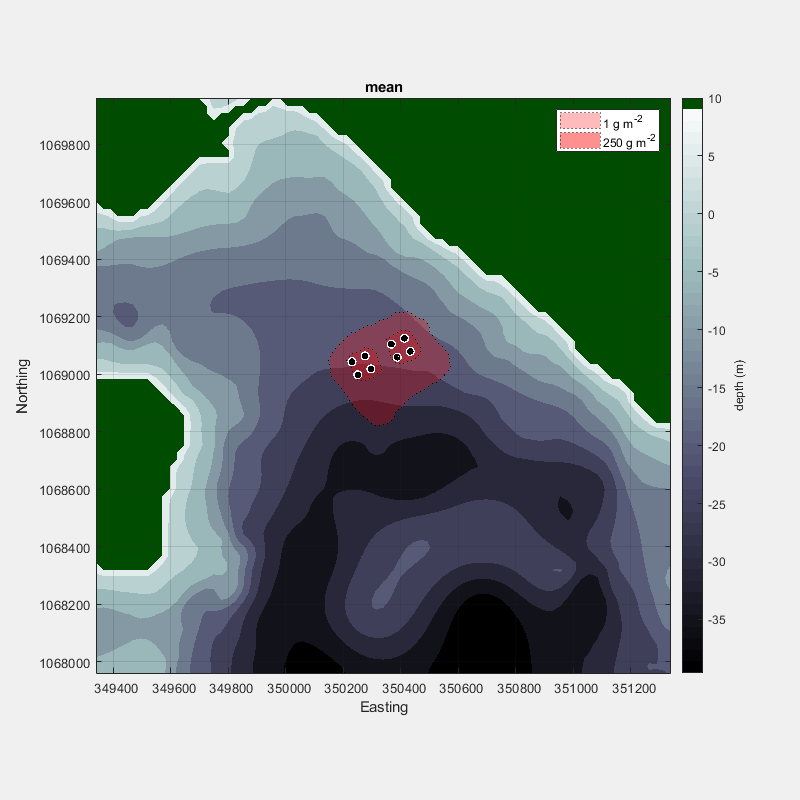

run.plot('sur', sur, 'levels', [1 250 1000]); 
title('mean')

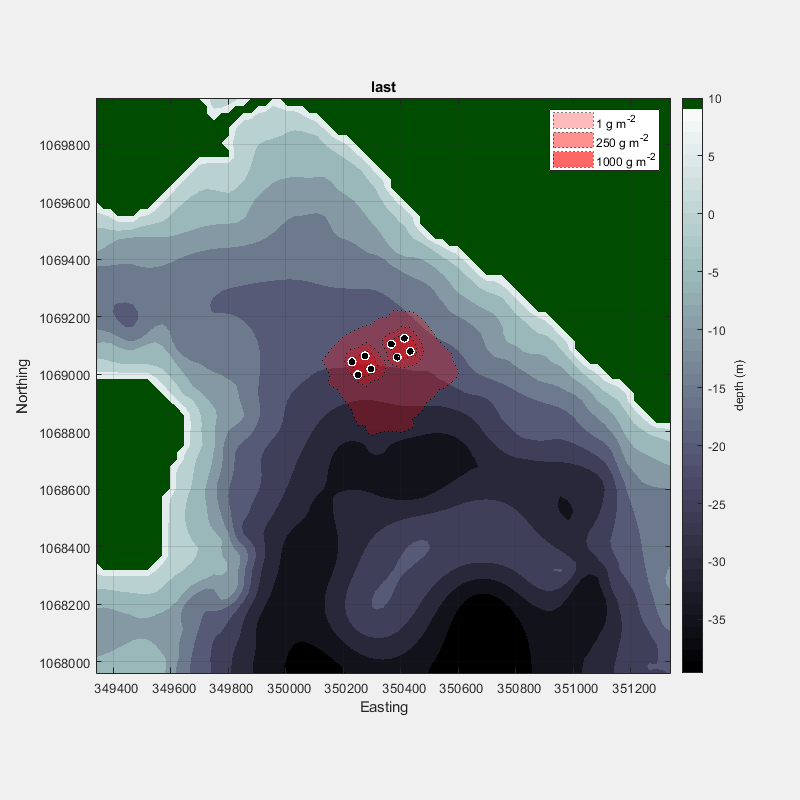

run.plot('sur', surs{end}, 'levels', [1 250 1000]); 
title('last')

As expected, the average impact is somewhere between the first and last impact extremes.

## Calculating percentile impacts through time

A similar approach can be used to calculate specific percentile impacts through time.

Again, clone a sur to hold the eventual values

sur = surs{1}.clone;

Define the percentiles we want, e.g. (these are just arbitrary for exposition purposes).

pctls = [10 50 90 95];

Calculate the respective seabed percentiles on a cell-by-cell basis

pctlSurData = Depomod.Stats.Utils.quantile(surData, pctls, 3, 'percentile', 1);

This uses the handy `.quantile()` function. Passed are the data (a 3-dimensional matrix), the list of percentiles we want and the dimension along which to return the percentiles (the final option simply indicates that the percentiles are quoted as full percentages rather than decimal fractions).

Check the size of the output

size(pctlSurData)

ans =      4    80    80


So we have four 80 x 80 datasets, each representing the cell-by-cell seabed impacts for different percentiles through time.

To analyse, we can add one of these representations to our sur object and calculate an area or make a plot. Here we'll look at the median - 50th percentile which is the second dataset in our results.

sur.Z = squeeze(pctlSurData(2, :, :)); 
sur.interpolate;    

We can now analyse and plot the derived sur.

sur.area(250)

ans =           19137.6540085766

This is just slightly smaller than the mean impact we measured previously.

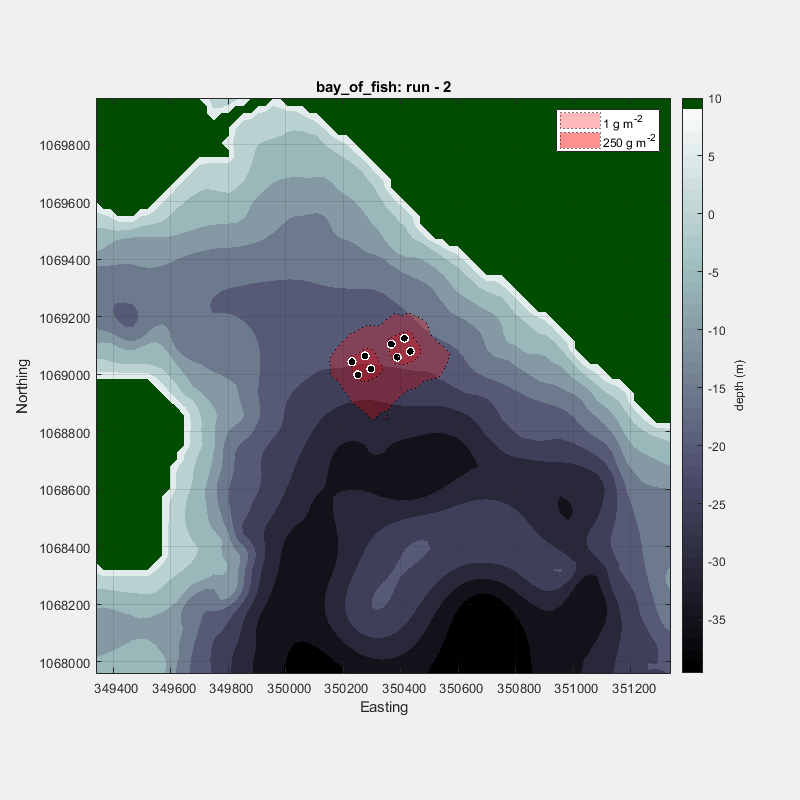

run.plot('sur', sur, 'levels', [1 250 1000]);